# **PID CONTROLLER DESIGN AND ANALYSIS**

# **ASSIGNMENT 2**

## **PROBLEM 1:**

#### a) Open-loop Analysis:

• Plot the step response of the open-loop system

• Calculate and report: rise time, settling time, peak overshoot, and steady-state error

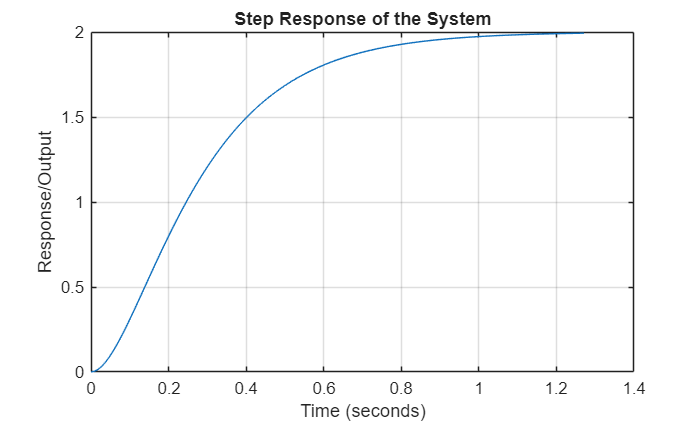

G=tf([100],[1 15 50]);
[y, t] = step(G);
plot(t, y);
title('Step Response of the System');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

info = stepinfo(G);
fprintf('Risetime:%.3f s\n', info.RiseTime);

Risetime:0.518 s


fprintf('Settling time: %.3f s\n', info.SettlingTime);

Settling time: 0.920 s


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 0.00%


fprintf('Peak:%.3f\n', info.Peak);

Peak:1.998


y_ss = y(end);
ess = 1 - y_ss; %%Unit Step

fprintf('SteadyState Error: %.3f\n', ess);

SteadyState Error: -0.993


#### b) P Controller Design:

• Design a proportional controller with Kp = 0.5 

• Plot the closed-loop step response 

• Report the performance metrics and steady-state error 

• Explain why steady-state error exists with only P control

C = pid(0.5,0,0);

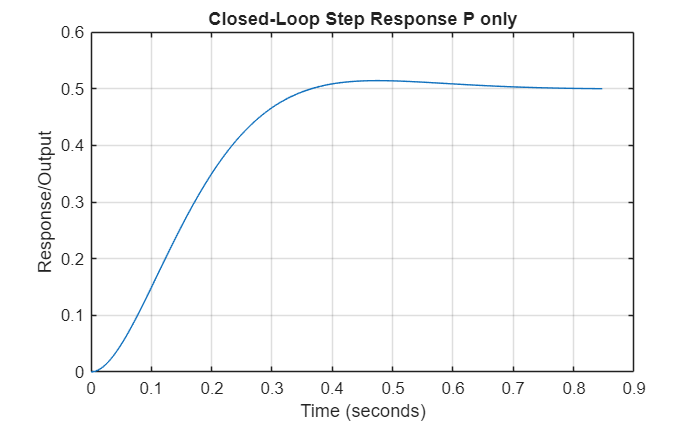

T= feedback(G*C, 1);
[y_closed, t_closed] = step(T);
plot(t_closed, y_closed);
title('Closed-Loop Step Response P only');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

info_closed = stepinfo(T);
fprintf('Risetime:%.3f s\n', info_closed.RiseTime);

Risetime:0.229 s


fprintf('Settling time: %.3f s\n', info_closed.SettlingTime);

Settling time: 0.574 s


fprintf('Overshoot: %.2f%%\n', info_closed.Overshoot);

Overshoot: 2.84%


fprintf('Peak:%.3f\n', info_closed.Peak);

Peak:0.514


y_ss_closed = y_closed(end);
ess_closed = 1 - y_ss_closed; %%Unit Step

fprintf('SteadyState Error: %.3f\n', ess_closed);

SteadyState Error: 0.500


In a unity-feedback system with only P control, a nonzero steady‑state error exists because the controller output is proportional to the error, so some error must remain to generate the control effort needed to balance the load and plant dynamics.

Physically,to hold a nonzero speed or position, the plant typically needs a constant input torque/voltage to balance friction and load, which the P controller provides as u=Kpe. And even the football field or drone example from the video resources.

####  c) PI Controller Design:

• Add integral action with Kp = 0.5, Ki = 1.5 

• Plot the step response and compare with P-only control 

• Report performance metrics 

• Discuss how integral action eliminated steady-state error

Ci = pid(0.5, 1.5, 0);

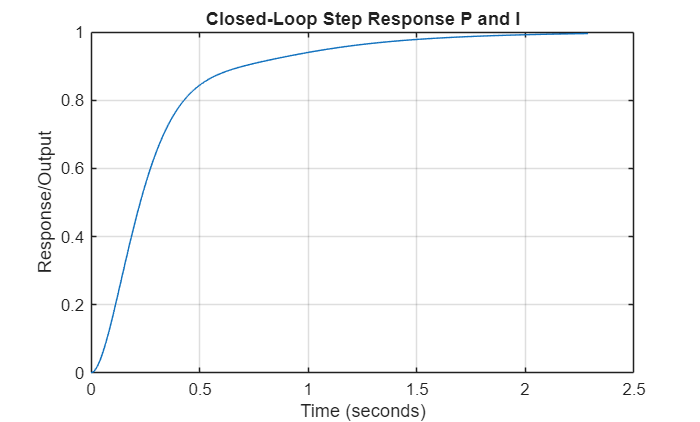

Ti= feedback(G*Ci, 1);
[y_closedi, t_closedi] = step(Ti);
plot(t_closedi, y_closedi);
title('Closed-Loop Step Response P and I');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

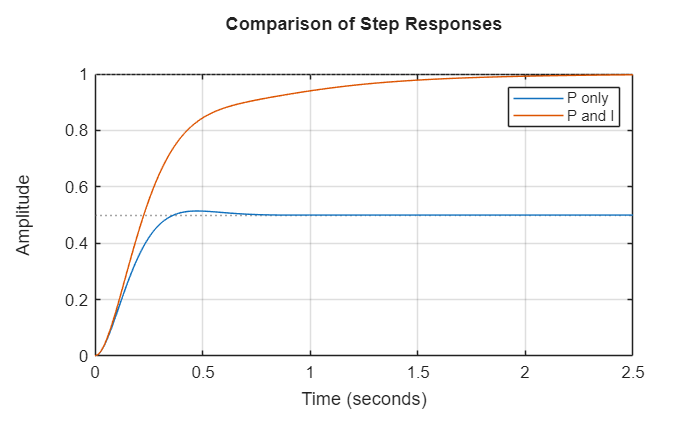

step(T, Ti);
grid on;
legend('P only', 'P and I');
title('Comparison of Step Responses');

info_closedi = stepinfo(Ti);
fprintf('Risetime:%.3f s\n', info_closedi.RiseTime);

Risetime:0.628 s


fprintf('Settling time: %.3f s\n', info_closedi.SettlingTime);

Settling time: 1.538 s


fprintf('Overshoot: %.2f%%\n', info_closedi.Overshoot);

Overshoot: 0.00%


fprintf('Peak:%.3f\n', info_closedi.Peak);

Peak:0.998


y_ss_closedi = y_closedi(end);
ess_closedi = 1 - y_ss_closedi; %%Unit Step
fprintf('SteadyState Error: %.3f\n', ess_closedi);

SteadyState Error: 0.004


Adding integral action makes the closed‑loop a TYPE-1 system, so for a step input the steady‑state error is driven essentially to zero because the integrator keeps changing the control signal as long as any error remains.

#### d) PID Controller Tuning:

• Tune the complete PID controller to achieve:

– Overshoot < 10%

– Settling time < 2 seconds

– Zero steady-state error 

• Report your final Kp, Ki, Kd values 

• Plot the final response with all metrics labeled

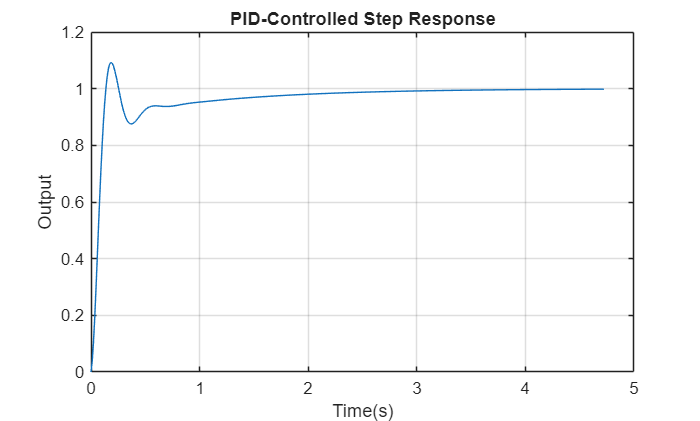

S = pidtune(G,'PID');
Kp = 3.0;
Ki = 2.99;
Kd = 0.02;
B= pid(Kp, Ki, Kd);
A = feedback(B*G, 1);
M = stepinfo(A);
[y_pid, t_pid] = step(A);
plot(t_pid, y_pid);
grid on;
title('PID-Controlled Step Response');
xlabel('Time(s)');
ylabel('Output');

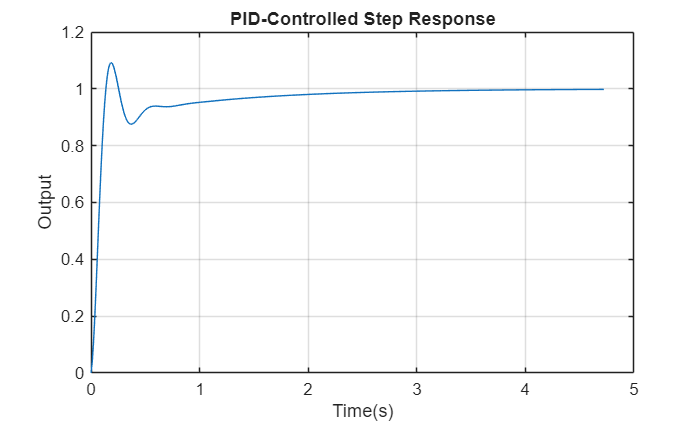

S = pidtune(G,'PID');
Kp = 3.0;
Ki = 2.99;
Kd = 0.02;
B= pid(Kp, Ki, Kd);
A = feedback(B*G, 1);
M = stepinfo(A);
[y_pid, t_pid] = step(A);
plot(t_pid, y_pid);
grid on;
title('PID-Controlled Step Response');
xlabel('Time(s)');
ylabel('Output');

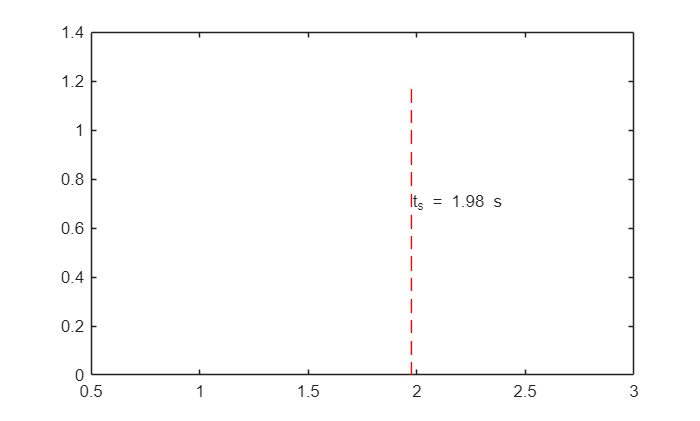

plot([M.SettlingTime M.SettlingTime], ylim, 'r--');
text(M.SettlingTime, mean(ylim), sprintf('t_s = %.2f s', M.SettlingTime));

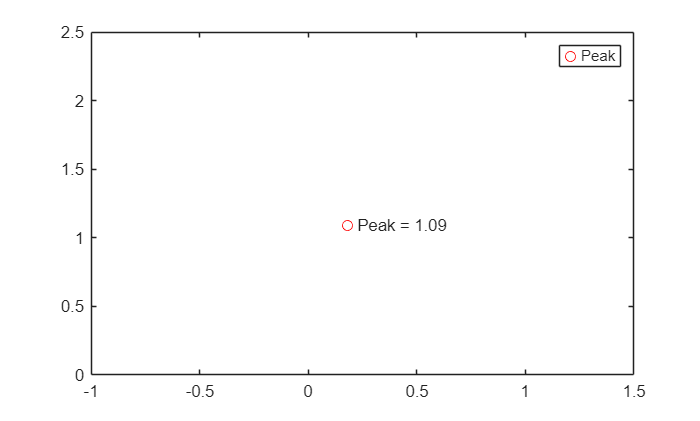

plot(M.PeakTime, M.Peak, 'ro');
text(M.PeakTime, M.Peak, sprintf('  Peak = %.2f', M.Peak));
legend('Peak');

info_pid = stepinfo(A);
fprintf('Risetime:%.3f s\n', info_pid.RiseTime);

Risetime:0.095 s


fprintf('Settling time: %.3f s\n', info_pid.SettlingTime);

Settling time: 1.975 s


fprintf('Overshoot: %.2f%%\n', info_pid.Overshoot);

Overshoot: 9.25%


fprintf('Peak:%.3f\n', info_pid.Peak);

Peak:1.092


y_ss_closedpid = y_pid(end);
ess_closedpid = 1 - y_ss_closedpid; %%Unit Step
fprintf('SteadyState Error: %.3f\n', ess_closedpid);

SteadyState Error: 0.002


## Problem 2:

#### a) Multi-Step Reference:

• Create a reference signal with multiple step changes:

– 0 to 1 at t=0s

– 1 to 1.5 at t=5s

– 1.5 to 0.8 at t=10s

– 0.8 to 1.2 at t=15s

• Simulate using lsim() and plot reference vs output 

• Calculate the tracking error over time

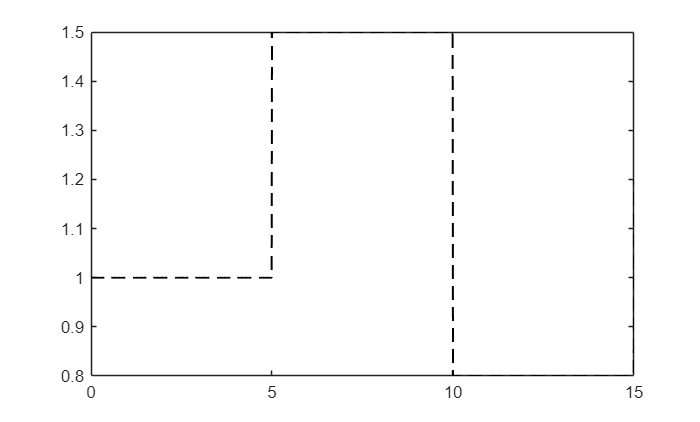

Kp = 3.0;
Ki = 2.99;
Kd = 0.02;
B= pid(Kp, Ki, Kd);
A = feedback(B*G, 1);
t = 0:0.01:15;
r = zeros(size(t));
r(t >= 0  & t < 5)  = 1;
r(t >= 5  & t < 10) = 1.5;
r(t >= 10 & t < 15) = 0.8;
r(t >= 15)          = 1.2;
[y_out, t_out] = lsim(A, r, t);
figure;
plot(t_out, r,  'k--' , 'LineWidth', 1.2);   % reference % k-- is for dotted lines

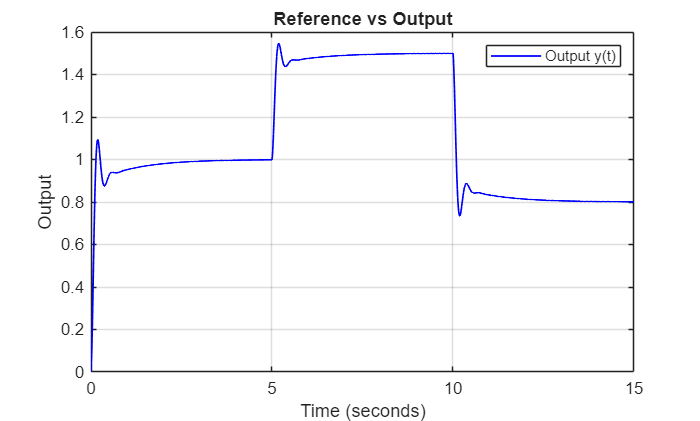

plot(t_out, y_out,  'b',   'LineWidth', 1.0);   % system output
title('Reference vs Output');
xlabel('Time (seconds)');
ylabel('Output');
grid on;
legend('Output y(t)');

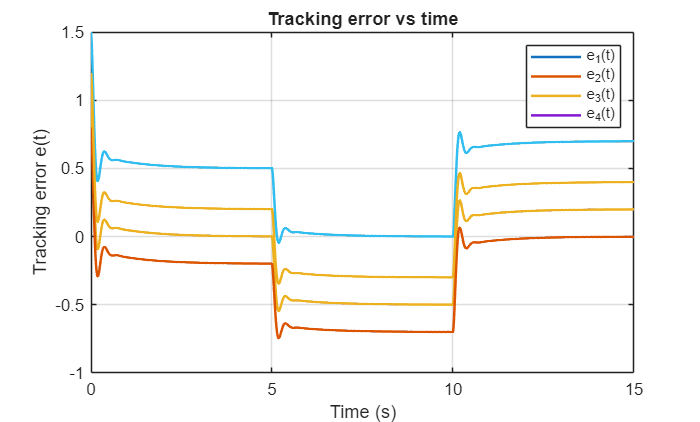

e = r - y_out;                  % tracking error at each time sample
figure; plot(t_out, e, 'LineWidth', 1.5); grid on;
xlabel('Time (s)');
ylabel('Tracking error e(t)');
title('Tracking error vs time');legend('e_1(t)','e_2(t)','e_3(t)','e_4(t)');

Nss  = round(0.1*length(t)) %using the last 10% samples as the steady state error

Nss = 150

ess  = mean(e(end-Nss+1:end));
fprintf('Mean Tracking Error: %.3f\n', ess);

Mean Tracking Error: 0.398


#### b) Ramp Input:

• Test your PID with a ramp input: r(t) = 0.2t for 0 ≤ t ≤ 20s 

• Plot reference, output, and error signals 

• Calculate the steady-state tracking error 

• Explain why PID may struggle with ramp tracking

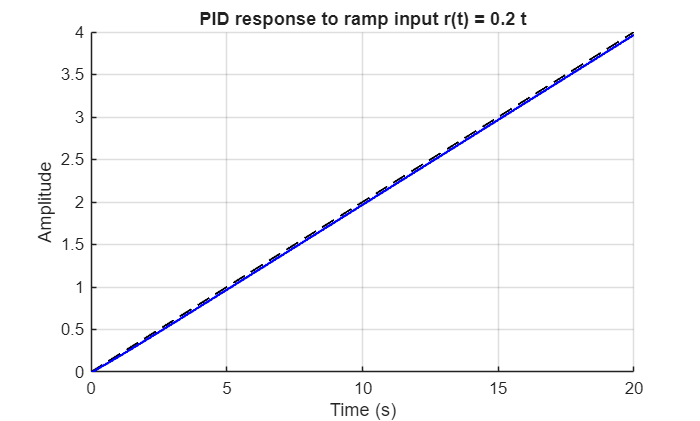

Kp = 3.0;
Ki = 2.99;
Kd = 0.02;
B= pid(Kp, Ki, Kd);
A = feedback(B*G, 1);
t = 0:0.01:20;
r = 0.2*t;
[y, t_out] = lsim(A, r, t);
figure; hold on; grid on;
plot(t_out, r, 'k--', 'LineWidth', 1.2);
plot(t_out, y, 'b',   'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('PID response to ramp input r(t) = 0.2 t');

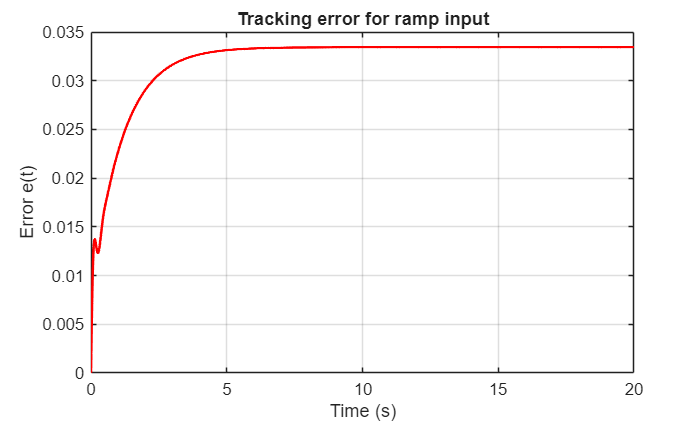

e = r(:) - y(:);
figure; plot(t_out, e, 'r', 'LineWidth', 1.5); grid on;
xlabel('Time (s)');
ylabel('Error e(t)');
title('Tracking error for ramp input');

% Calculate and display the steady-state error for the ramp input
ess_ramp = mean(e(end-Nss+1:end));
fprintf('Mean Tracking Error for Ramp Input: %.3f\n', ess_ramp);

Mean Tracking Error for Ramp Input: 0.033


PID may struggle with ramp tracking because a standard PID loop usually behaves like a type‑1 system, which cannot perfectly follow a ramp with zero error unless its gains are chosen to make the effective system type 2.

#### c) Sinusoidal Reference:

• Apply a sinusoidal reference: r(t) = sin(0.5t) for 0 ≤ t ≤ 20s 

• Plot the tracking performance 

• Calculate the phase lag between reference and output 

• Discuss which PID parameter (P, I, or D) most affects sinusoidal tracking

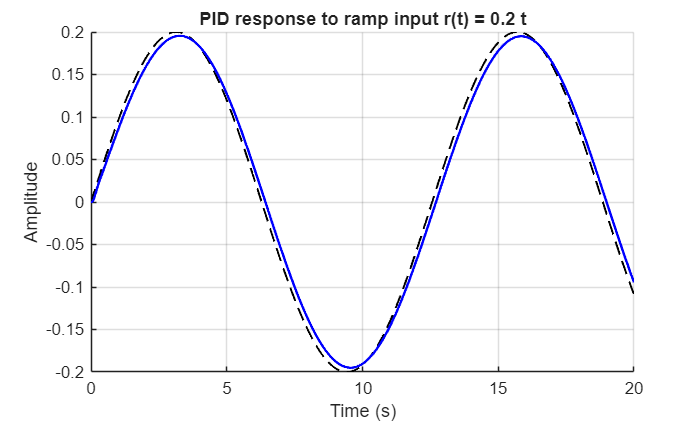


t = 0:0.01:20;
r = 0.2*sin(0.5*t);
[y, t_out] = lsim(A, r, t);
figure; hold on; grid on;
plot(t_out, r, 'k--', 'LineWidth', 1.2);
plot(t_out, y, 'b',   'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('PID response to ramp input r(t) = 0.2 t');

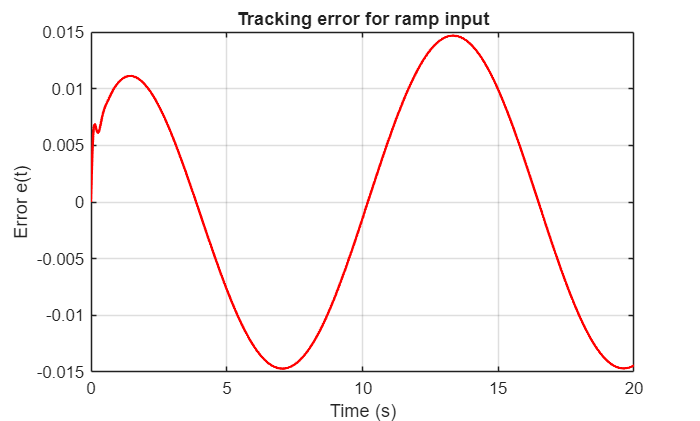

e = r(:) - y(:);
figure; plot(t_out, e, 'r', 'LineWidth', 1.5); grid on;
xlabel('Time (s)');
ylabel('Error e(t)');
title('Tracking error for ramp input');

omega = 0.5;
T = 2*pi/omega;
r_ss = r(:);
y_ss = y(:);

[xc, lags] = xcorr(y_ss, r_ss, 'coeff');      % cross-correlation
[~, idx]   = max(xc);                         % lag of best alignment
lag_samples = lags(idx);                      % sample shift (y vs r)

dt   = t(2) - t(1);                           % sampling time
Delta_t = lag_samples * dt;                   % time delay
omega = 0.5;                                
phi_deg = omega * Delta_t * 180/pi;           % phase difference in degrees

fprintf('Phase difference ≈ %.2f degrees\n', phi_deg);

Phase difference ≈ 2.29 degrees


Sinusoidal tracking is most sensitive to the P and D terms; the I term mainly adds low‑frequency lag and can hurt sinusoidal tracking if too large.

- P mainly sets how closely the output amplitude follows the sine; higher Kp*K**p* improves gain tracking but can increase lag/overshoot.

- I is best for step offsets; at sinusoidal frequency it adds phase lag and can actually worsen tracking if too large.

- D is the most helpful for sinusoidal tracking; it adds phase lead and increases bandwidth, reducing phase lag between reference and output.